# Keanu Francis 

Assignement 3

Z#23456741

# ChatGPT experiments

## Example 1

### Prompt: write MATLAB code to isolate text from an image

### Solution:

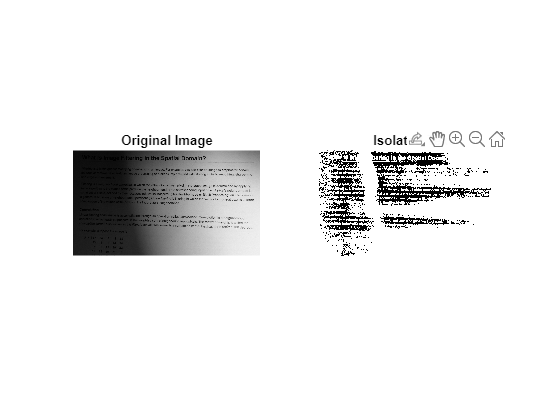

% Read the image
img = imread('printedtext.png');

% Convert the image to grayscale
%had to change the rgb2gray to im2gray 
img_gray = im2gray(img);
% Apply adaptive thresholding to the grayscale image
img_bw = imbinarize(img_gray, 'adaptive');

% Remove small objects (noise) from the binary image
img_bw = bwareaopen(img_bw, 50);

% Invert the binary image to get the text
img_text = imcomplement(img_bw);

% Display the original and isolated text images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_text);
title('Isolated Text');

### Explanation:

This code will first convert the image to grayscale, then apply an adaptive thresholding method to convert the grayscale image to binary. The `bwareaopen` function is then used to remove any small objects (noise) from the binary image. Finally, the binary image is inverted using `imcomplement` to get the isolated text. The original and isolated text images are displayed using `imshow`.

### Notes: 

small error when unsing rgb2gray(img) had to change ti im2gray() the imbinarize approch is to agressice and would need to be tuned for this specific image

### Limitations:

Does causes an error for grey scale images im binarize with adaptinive threshholding can be too agressive with images with little contrast

## Example 2

### Prompt:Write MATLAB code to add a moton blur effect to an image

### Solution:

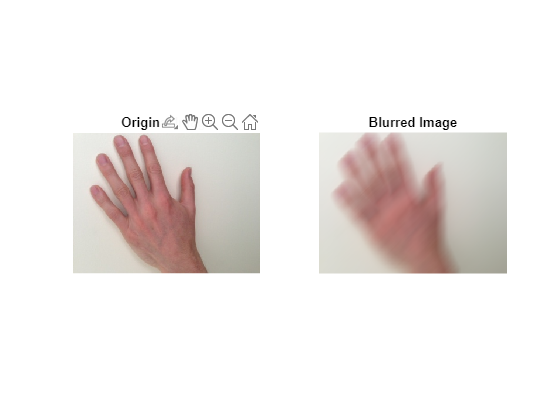

% Read the image
img = imread('hands2.jpg');

% Create a motion blur kernel
h = fspecial('motion', 30, 45);

% Apply the motion blur effect to the image
img_blurred = imfilter(img, h, 'replicate');

% Display the original and blurred images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_blurred);
title('Blurred Image');

### Explanation:

This code uses the `fspecial` function to create a motion blur kernel (`h`) with a length of 30 and an angle of 45 degrees. The `imfilter` function is then used to apply the motion blur effect to the image, using the `replicate` boundary option to extend the image boundary. Finally, the original and blurred images are displayed using `imshow`.

### Notes:

works sucessfully without alterations however the effect is applied to the entire image

### Limitations: 

if there is a situation where we would need only a single part of an image for example: a person running, the motion blur effect would only be needed to apply to the person.

## Example 3

### Prompt: Write MATLAB code to detect if there are cars in an image

### Solution:

% Read the image
img = imread('car2.jpg');

% Load the pre-trained object detector
detector = vision.CascadeObjectDetector('cars.xml');

Error using vision.CascadeObjectDetector
Unable to find cars.xml.


% Detect cars in the image
bboxes = step(detector, img);

% Display the results
imshow(img);
hold on;
for i = 1:size(bboxes,1)
    rectangle('Position',bboxes(i,:),'LineWidth',2,'EdgeColor','r');
end
title('Detected Cars');
hold off;

### Explanation:

This code uses the `vision.CascadeObjectDetector` function to load a pre-trained object detector trained to detect cars. The `step` function is then used to detect cars in the image. The bounding boxes of the detected cars are stored in the `bboxes` variable. Finally, the image and the bounding boxes are displayed using `imshow` and `rectangle`. The `hold on` and `hold off` commands are used to allow multiple rectangles to be displayed on the same image.

### Notes: 

vision.CascadeObjectDetector('cars.xml') does not contain have a pretrained model for cars w seperate model would have to be trained and used on cars

### Limitations:

## Example 4

### Prompt: Write matlab code to produce the negative of an image

### Solution:

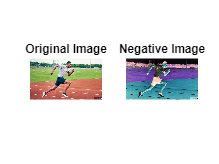

% Read the image
img = imread("running.PNG");

% Convert the image to double type
img = im2double(img);

% Calculate the negative of the image
img_negative = 1 - img;

% Display the original and negative images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_negative);
title('Negative Image');

### Explanation:

This code uses the `im2double` function to convert the image to double type, allowing for better manipulation of the image data. The negative of the image is then calculated by subtracting the image from 1. Finally, the original and negative images are displayed using `imshow`.

### Notes:

### Limitations:

## Example 5

### Prompt: Write a MATLAB program that can perform Anti-aliasing on an image

### Solution:

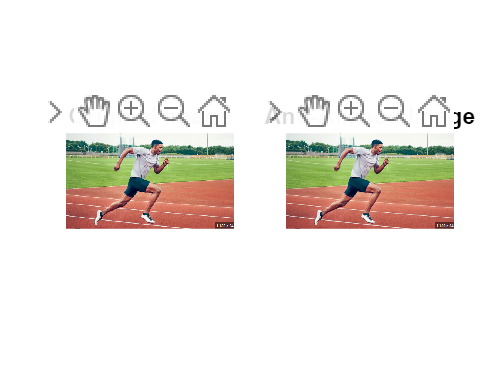

% Read the image
img = imread('running.PNG');

% Resize the image with anti-aliasing
%increaced the resize of the image instead of decreacing it
img_anti_aliased = imresize(img, 2, 'Antialiasing', true);

% Display the original and anti-aliased images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_anti_aliased);
title('Anti-Aliased Image');

### Explanation:

This code uses the `imresize` function to resize the image to half of its original size, with the `Antialiasing` option set to `true`. This option applies anti-aliasing to the resizing process, producing a smoother and more visually appealing result. Finally, the original and anti-aliased images are displayed using `imshow`.

### Notes:

aliasing does not seem to be significantly decreaced until there is an increace in size 

### Limitations:

causes larger file sizes.

## Example 6

### Prompt:Write MATLAB code isolate the RGB channels in an image

### Solution:

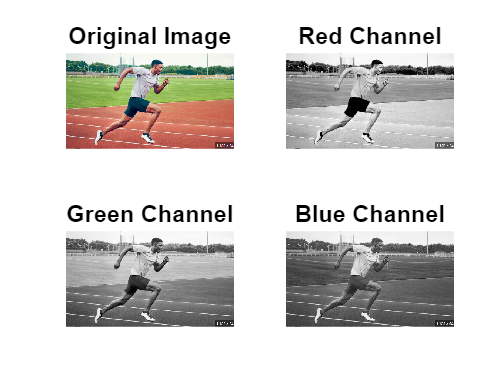

% Read the image
img = imread('running.PNG');

% Split the image into its RGB channels
R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

% Display the original image and its RGB channels
figure;
subplot(2,2,1);
imshow(img);
title('Original Image');
subplot(2,2,2);
imshow(R);
title('Red Channel');
subplot(2,2,3);
imshow(G);
title('Green Channel');
subplot(2,2,4);
imshow(B);
title('Blue Channel');

### Explanation:

This code uses the colon operator (`:`) to select all rows and columns of each RGB color channel in the image. The individual color channels are then stored in separate variables (`R`, `G`, and `B`). Finally, the original image and its RGB channels are displayed using `imshow`.

### Notes:

Only shows the images as greyscale would have prefered if they showed a color image denoting each color  

### Limitations:

## Example 7

### Prompt: Write matlab code to perform tone mapping on a image 

### Solution:

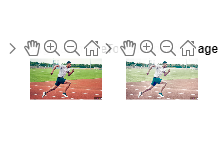

% Read the image
img = imread("running.PNG");

% Convert the image to double type
img = im2double(img);

% Perform tone mapping using the Reinhard algorithm
img_tone_mapped = tonemap(img,'AdjustLightness', [0.1 1], 'AdjustSaturation', 1.2);

% Display the original and tone mapped images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_tone_mapped);
title('Tone Mapped Image');

### Explanation:

This code uses the `im2double` function to convert the image to double type, allowing for better manipulation of the image data. The tone mapping is performed using the `tonemap` function with the Reinhard algorithm, which is a global tone mapping algorithm that maps the brightness and contrast of an image to a range that is suitable for display. The `AdjustLightness` and `AdjustSaturation` options are used to adjust the lightness and saturation of the tone mapped image. Finally, the original and tone mapped images are displayed using `imshow`.

### Notes:

The Reinhard algorithm is one of the several types of tone mapping more exploration could be done to see other algorithms

### Limitations:

need adjusting to avoid loosing contrast.

## Example 8

### Prompt:Write MATLAB code to apply a bloom effect to the brightest parts of an image

### Solution:

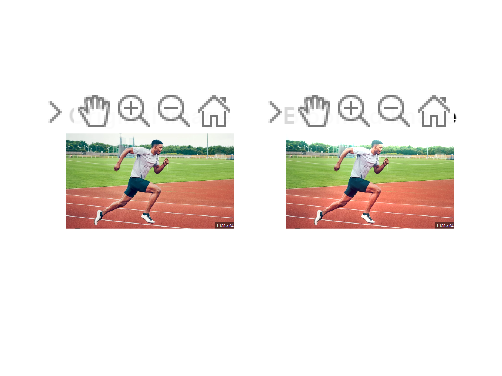

% Read the image
img = imread('running.PNG');

% Convert the image to double type
img = im2double(img);

% Extract the brightest parts of the image
img_brightest = imadjust(img, [0.8 1], [0 1], 1.5);

% Create a Gaussian kernel for the bloom effect
sigma = 20;
kernel_size = 2*ceil(3*sigma)+1;
kernel = fspecial('gaussian', kernel_size, sigma);

% Apply the bloom effect to the brightest parts of the image
img_bloom = img;
for i=1:3
    img_bloom(:,:,i) = img_bloom(:,:,i) + imfilter(img_brightest(:,:,i), kernel, 'replicate');
end

% Display the original and bloomed images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_bloom);
title('Bloomed Image');

### Explanation:

This code uses the `imadjust` function to extract the brightest parts of the image. The `fspecial` function is then used to create a Gaussian kernel with a specified size and standard deviation. The `imfilter` function is used to convolve the brightest parts of the image with the Gaussian kernel, creating the bloom effect. Finally, the original and bloomed images are displayed using `imshow`.

### Notes:

### Limitations:

## Example 9

### Prompt:Write matlab code to find the depth of an image

### Solution:

% Read the left and right stereo images
left_image = imread('yellowstone_left.png');
right_image = imread('yellowstone_right.png');

% Convert the images to grayscale
left_gray = rgb2gray(left_image);
right_gray = rgb2gray(right_image);

% Estimate the disparity map using the block matching algorithm
disparity_range = [-64, 64];
block_size = 21;
disparity_map = disparity(left_gray, right_gray, 'Method', 'BlockMatching', 'DisparityRange', disparity_range, 'BlockSize', block_size);

% Calculate the depth map using the stereoParameters object
load('stereoParams.mat'); % load the stereo parameters obtained from camera calibration


Unrecognized function or variable 'poseCamera2'.

focal_length = stereoParams.CameraParameters1.FocalLength;
baseline = norm(stereoParams.TranslationOfCamera2);
depth_map = baseline*focal_length./disparity_map;

% Display the depth map
figure;
imshow(depth_map, []);
title('Depth Map');
colormap jet;
colorbar;
This code uses the disparity function to estimate the disparity map of the stereo images using the block matching algorithm, which searches for matching blocks between the left and right images. The stereoParams object is loaded from a file containing the camera calibration data, which includes the intrinsic and extrinsic parameters of the stereo camera. The depth map is then calculated using the formula depth = baseline * focal_length / disparity, where baseline is the distance between the two camera centers and focal_length is the focal length of the camera. Finally, the depth map is displayed using imshow with a colormap and colorbar.






### Explanation:

This code uses the `disparity` function to estimate the disparity map of the stereo images using the block matching algorithm, which searches for matching blocks between the left and right images. The `stereoParams` object is loaded from a file containing the camera calibration data, which includes the intrinsic and extrinsic parameters of the stereo camera. The depth map is then calculated using the formula `depth = baseline * focal_length / disparity`, where `baseline` is the distance between the two camera centers and `focal_length` is the focal length of the camera. Finally, the depth map is displayed using `imshow` with a colormap and colorbar.

### Notes:

needs camera parameters in order to function 

### Limitations:

requires two images

## Example 10

### Prompt: Write matlab code to adjust the temperature of an image

### Solution:

% Read the image
img = imread('running.PNG');

% Convert the image to double type
img = im2double(img);

% Calculate the color temperature of the image
temp = colorTemperature(img);

Unrecognized function or variable 'colorTemperature'.


% Adjust the color temperature to a desired value (in Kelvin)
new_temp = 5500;

% Compute the color balance matrix
CBM = chromadapt(eye(3),temp,new_temp);

% Apply the color balance matrix to the image
img_adjusted = applycform(img, makecform('colorbalance', CBM));

% Display the original and adjusted images
figure;
subplot(1,2,1);
imshow(img);
title('Original Image');
subplot(1,2,2);
imshow(img_adjusted);
title('Adjusted Image');

### Explanation:

This code uses the `colorTemperature` function from the Image Processing Toolbox to estimate the color temperature of the image based on its white balance. The `chromadapt` function is used to compute the color balance matrix that will adjust the temperature of the image to the desired value. Finally, the `applycform` function is used to apply the color balance matrix to the image, resulting in an adjusted image with the desired temperature. The original and adjusted images are displayed using `imshow`. Note that this method assumes that the image has a natural white balance and does not have any dominant color cast. If the image has a strong color cast or is subject to non-uniform lighting conditions, a more advanced color correction algorithm may be necessary.

### Notes: 

Does not work since there is no colorTemperature function in image processing toolbox one would have to be created.

### Limitations: